# *E.coli *Core Model for Beginners (PART 2)

(please run PART 1 of this tutorial first)

## 3. Flux Balance Analysis

Flux balance analysis (FBA) is used to calculate the flow of metabolites through a metabolic network making it possible to predict an organism's growth-rate or the production-rate of a bioproduct. Combining the stoichiometric matrix and the objective function can create a system of linear equations that can be used to calculate the fluxes through all the reactions in the network. In flux balance analysis, these equations are solved using linear programming algorithms that can quickly identify optimal solutions to large systems of equations. 

Once the external conditions have been set, which include 1) **defining the allowed carbon sources**, 2)** defining the oxygen uptake level**, and 3) **setting the objective function**, then the simulation conditions are setup to perform FBA. This is accomplished through the use of the "**optimizeCbModel(model,osenseStr)**", a COBRA toolbox function where the first argument is the model name and the second argument determines if the optimization algorithm maximizes ('max') or minimizes ('min') the objective function. Below is an example for an aerobic environment with glucose as the carbon source optimizing for maximum growth-rate. *[Timing: Seconds]*

model = e_coli_core; % Starting with the original model
model = changeRxnBounds(model,'EX_glc(e)',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2(e)',-30,'l'); % Set maximum oxygen uptake
model = changeObjective(model,'Biomass_Ecoli_core_w_GAM'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max') % FBA analysis

FBAsolution = struct with fields:
    origStatText: []
               f: 0.8739
               v: [95×1 double]
               y: [72×1 double]
               w: [95×1 double]
               s: [72×1 double]
          solver: 'gurobi'
       algorithm: 'default'
            stat: 1
        origStat: 'OPTIMAL'
            time: 0.0090
           basis: [1×1 struct]
          vars_v: []
               x: [95×1 double]


**“FBAsolution”** is a Matlab structure that contains the following outputs.  “**FBAsolution.f “ is the value of objective function** as calculated by FBA, thus if the biomass reaction is the objective function then “FBAsolution.f" corresponds to the growth-rate of the cell. In the example above, it can be seen that the growth-rate "FBAsolution.f" is listed as 0.8739 ${\textrm{hr}}^{-1}$.** “FBAsolution.x” is a vector listing the calculated fluxes flowing through the network. “FBAsolution.y” and “FBAsolution.w” contain vectors representing the shadow prices and reduced costs for each metabolite or reaction, respectively.**

The flux values found in the structure "FBAsolution.x"  can be printed out using the "**printFluxVector(model,fluxData,nonZeroFlag,excFlag)**" where the second argument is a vector of the flux values, the nonZeroFlag only prints nonzero rows (Default = false), and excFlag only prints exchange reaction fluxes (Default = false). Examples of printing non-zero fluxes and exchange reaction only fluxes are shown below. *[Timing: Seconds]*

printFluxVector(model,FBAsolution.x,true) % only prints nonzero rows

ACONTa              	       6.007
ACONTb              	       6.007
AKGDH               	       5.064
ATPM                	        8.39
ATPS4r              	       45.51
Biomass_Ecoli_core_w_GAM	      0.8739
CO2t                	      -22.81
CS                  	       6.007
CYTBD               	        43.6
ENO                 	       14.72
EX_co2(e)           	       22.81
EX_glc(e)           	         -10
EX_h(e)             	       17.53
EX_h2o(e)           	       29.18
EX_nh4(e)           	      -4.765
EX_o2(e)            	       -21.8
EX_pi(e)            	      -3.215
FBA                 	       7.477
FRD7                	       994.9
FUM                 	       5.064
G6PDH2r             	        4.96
GAPD                	       16.02
GLCpts              	          10
GLNS                	      0.2235
GLUDy               	      -4.542
GND                 	        4.96
H2Ot                	      -29.18
ICDHyr              	       6.007
MDH                 	       5.064
NADH16    

printFluxVector(model,FBAsolution.x,true,true) % only print exchange reaction fluxes 

Biomass_Ecoli_core_w_GAM	      0.8739
EX_co2(e)           	       22.81
EX_glc(e)           	         -10
EX_h(e)             	       17.53
EX_h2o(e)           	       29.18
EX_nh4(e)           	      -4.765
EX_o2(e)            	       -21.8
EX_pi(e)            	      -3.215


Printing all the zero and nonzero fluxes can be achieved using "printFluxVector(model,FBAsolution.x)." 

These** fluxes can also be overlayed on a map of the model** as shown below,  *[Timing: Seconds]*

map=readCbMap('ecoli_core_map');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawFlux(map, model, FBAsolution.x, options); % Draw the flux values on the map "target.svg"

Document Written


This overlayed map will be written to a file named "target.svg" that should be located in your working directory. Figure 7 is a screenshot of that map.

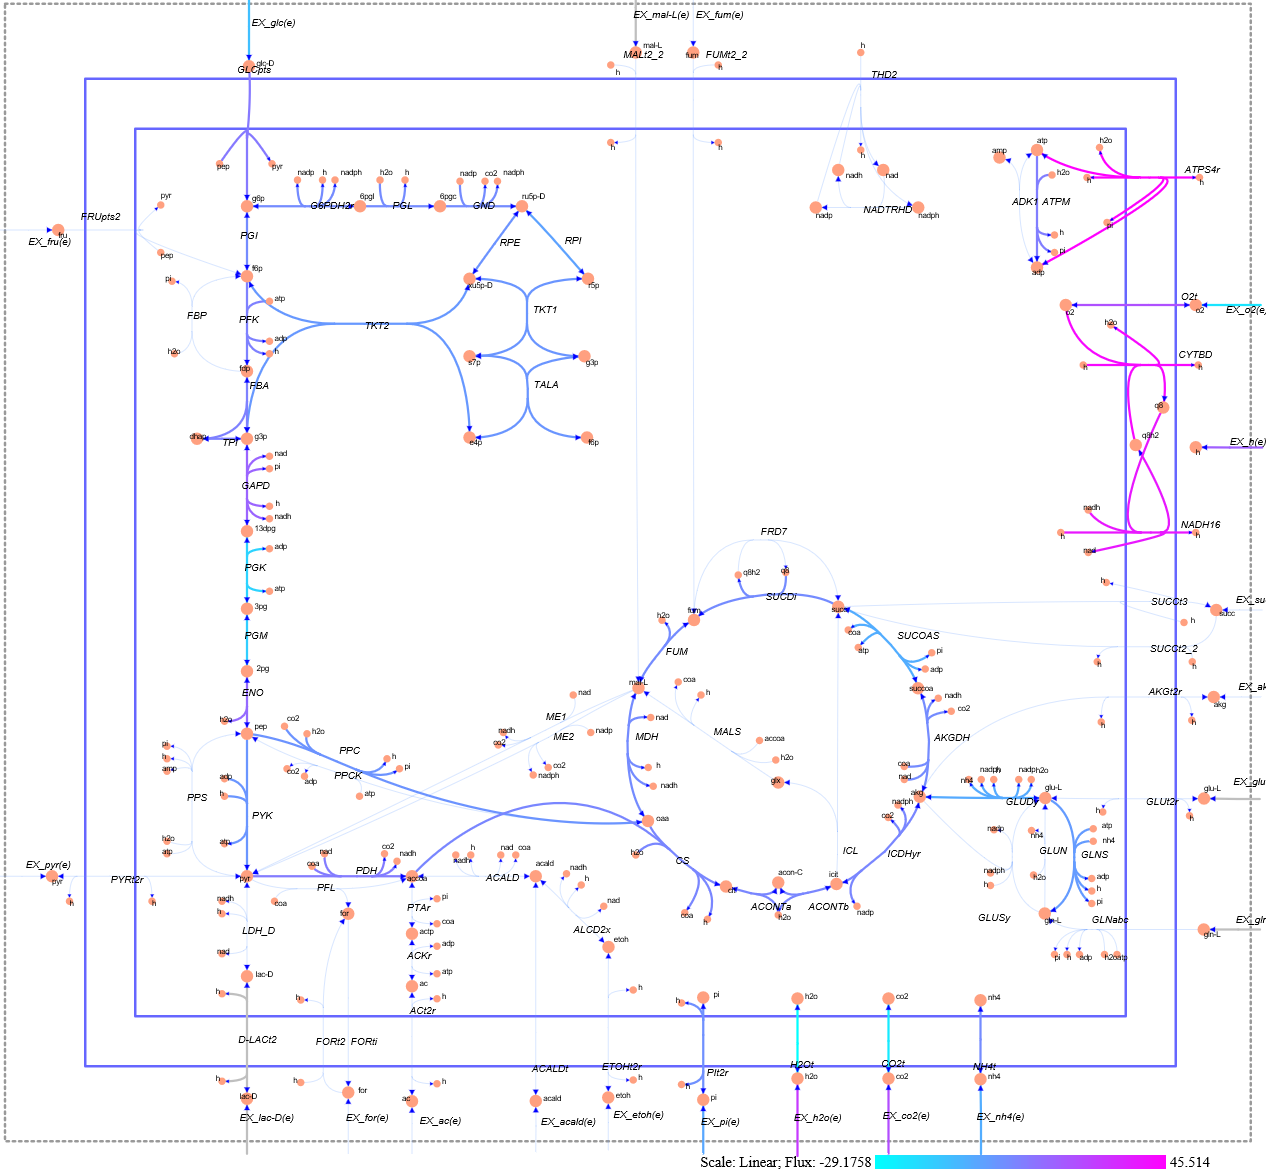

**                        Figure 7.** Screenshot of the network map of the *E.coli* core model with EX_glc(e) $\ge$ -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ and EX_o2(e) $\ge$ -30 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$.

As a cautionary note, the default condition for the* E.coli *core model sets the carbon source as glucose with an uptake rate of -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$, the oxygen uptake is -1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ which implies an aerobic environment with the objectve function defined as 'Biomass_Ecoli_core_w_GAM'. It is a good practice to define the conditions of your simulation explicity to avoid unexpected results and long troubleshooting times.

## 4. The Subsystems of the *E.coli *Core Model

Now with these basic Matlab and COBRA toolbox skills behind us, it is time to start exploring the **subsytems that make up the *****E.coli***** core model**. We will start by looking at the "energy production and management" section of the model that is referred to as the "oxidative phosphorylation" subsystem in this core model. This subsystem is located in the upper right corner of the *E.coli *core map as shown below in Figure 8.

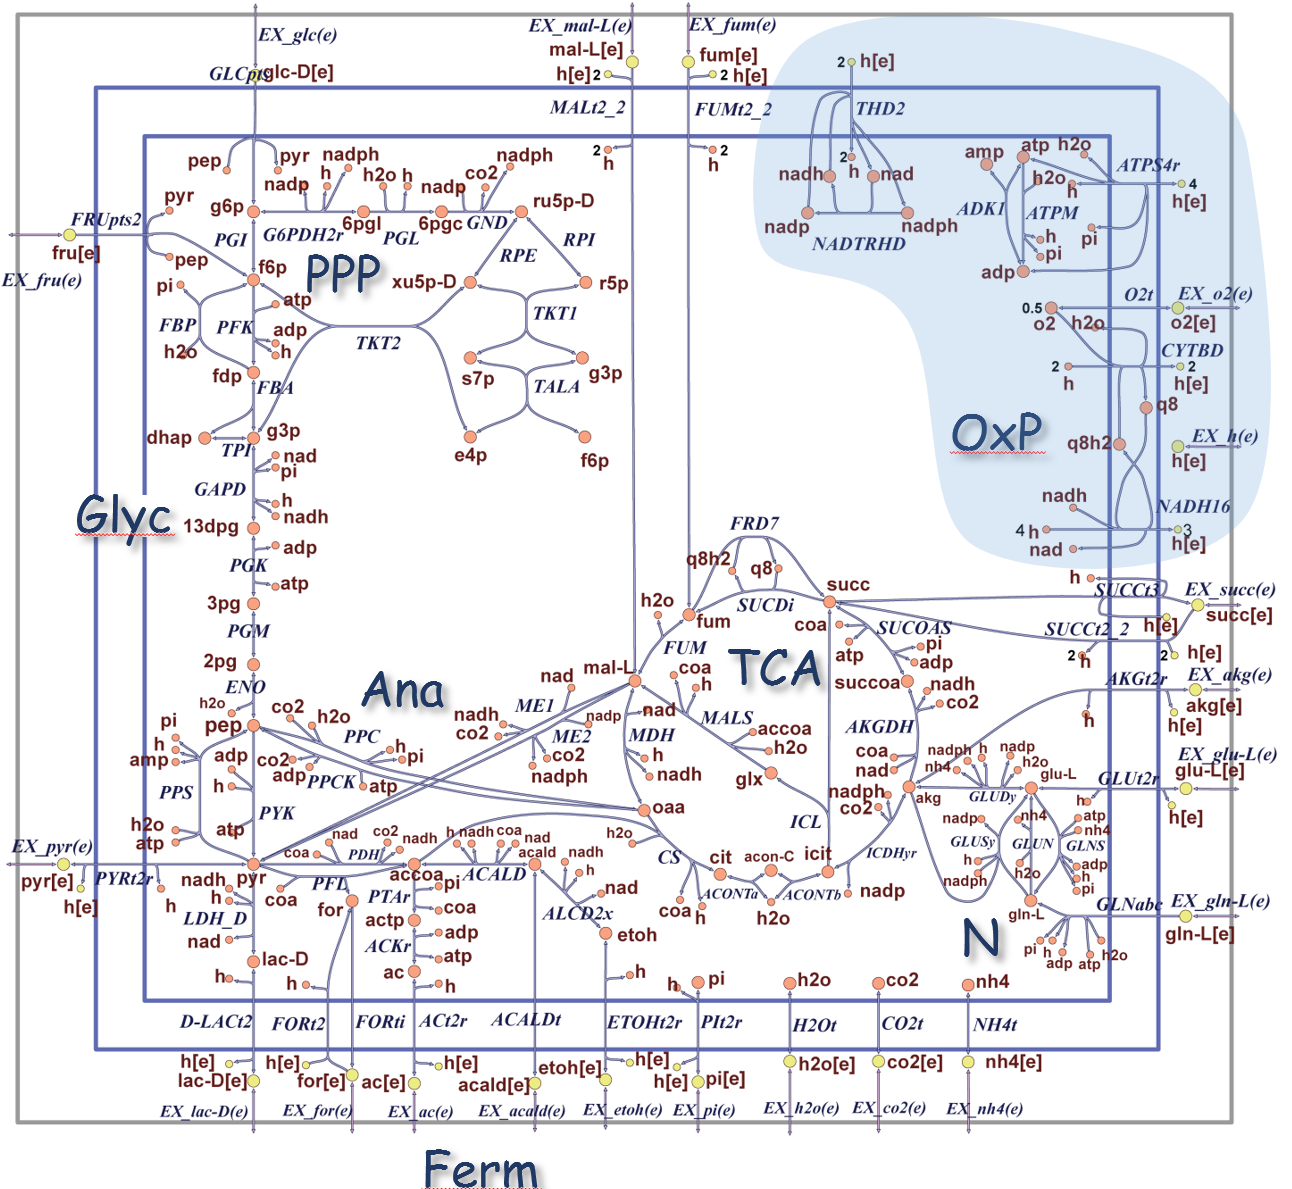

**                                                Figure 8.** The location of the energy management subsystem and it's reactions highlighted in blue on the *E.coli *core map [3].

As you will see in this section, this subsystem not only includes the reactions for oxydative phosphorylation, it also includes reactions that are required for managing the reducing power needed in the cell. This subsystem will be followed by an exploration of the glycolysis pathway, the pentose phosphate pathway, the tricarboxylic acid cycle, the glycoxylate cycle, gluconeogenesis, and anapleurotic reactions, fermentation pathways, and the nitrogen metabolism.

**4.A. Energy Production & Management**

Perhaps the most important requirement of an operational cell is the **production and management of energy and reducing power**. There are two main mechanisms available within the *E.coli* core model for the **production of ATP (atp[c]) energy: 1) substrate level phosphorylation, and 2) oxidative phosphorylation through the use of the electron transport chain.** Substrate level phosphorylation occurs when specific metabolic pathways within the cell are net producers of energy. In these cases, atp[c] is formed by a reaction between ADP (adp[c]) and a phosphorylated intermediate within the pathway. In the core model this occurs in the glycolysis pathway with both phosphoglycerate kinase (PGK), and pyruvate kinase (PYK), and in the tricarboxylic acid cycle with succinyl-CoA synthetase (SUCOAS). Through these **substrate level phosphorylation enzymes each molecule of glucose can potentially add four molecules to the total cellular flux of atp[c].** 

The second mechanism for energy generation is **oxidative phosphorylation through the electron transport chain, which under aerobic conditions, produces the bulk of the cell's atp[c]**. In the simple core model, the electron transport chain is used to transport protons (h[c]) from the cytoplasm across the cytoplasmic membrane into the extracellular space (periplasmic space in actual cells) to create a **proton-motive force which drives ATP synthase (ATPS4r) to produce atp[c]**. 

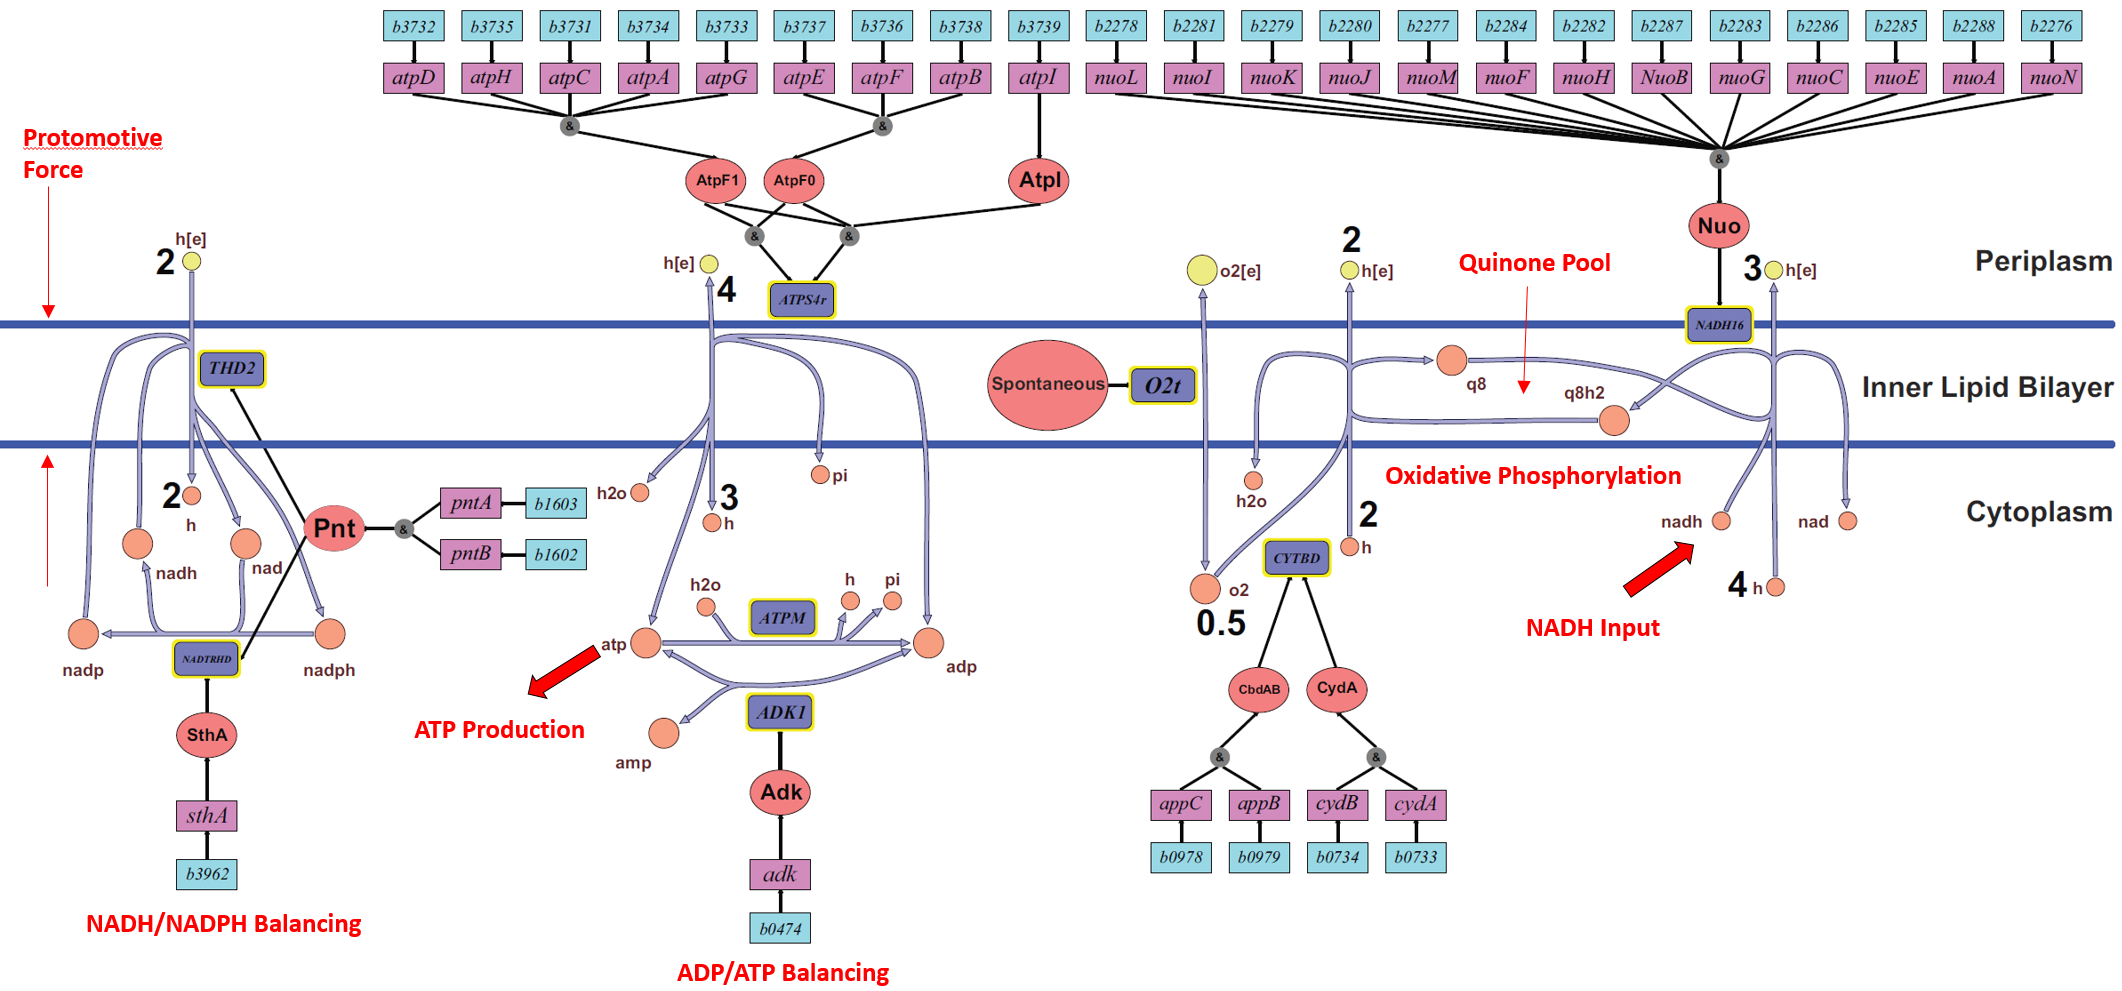

**                                                                        Figure 9. **Oxidative Phosphorylation and Transfer of Reducing Equivalents [3].

***Aerobic Respiration***

For** aerobic respiration, the primary source of atp[c] is produced through oxidative phosphorylation**. This is illustrated in Figure 9 where **NADH** (nadh[c]), acting as a substrate for NADH dehydrogenase (NADH16),** provides the reducing power necessary to trigger the electron transport chain**. The ***E. coli *****core model combines the electron transport chain into two reactions**. In the first of these two reactions, NADH16 catalyzes the oxidation of nadh[c] to form NAD+ (nad[c]) while extracting four protons (h[c]) from the cytoplasm. It then transports** three protons to the extracellular space** while **combining the fourth proton with a proton and two electrons from NADH** to **transform ubiquinone-8) (q8[c]) to its reduced form ubiquinol-8 (q8h2[c])**. Both q8[c] and q8h2[c] are oil soluble coenzymes that can diffuse freely within the lipid environment of the cytoplasmic membrane **allows q8h2[c] to eventually transfer its two electrons and two protons to cytochrome oxidase (CYTBD**). The **two protons (h[e]) are then transferred into the extracellular space where they add to the proton-motive force.** The** two electrons from q8h2[c] are then combined with two cytoplasmic protons and an oxygen atom, the terminal electron acceptor, to form water**. In this model,** oxygen (o2[c]) spontaneously diffuses** from the environment into the cell through the spontaneous 02t reaction. 

With a **proton-motive force now created by the pumping of protons from the cytoplasm to the extracellular space**, the reaction **ATPS4r** **can synthesize atp[c] from adp[c**]. For this simple model the *P*/0 ratio is stoichiometrically set to 1.25. Another reaction included in the energy management suite is adenylate kinase (ADK1), a phosphotransferase enzyme that catalyzes the interconversion of adenine nucleotides, and plays an important role in the **adp[c]/atp[c] balance or cellular energy homeostasis**.

Finally, the** ATP maintenance function (ATPM), which is set at 8.39 **$\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$** accounts for the energy** (in form of atp[c]) necessary to replicate a cell, including for macromolecular synthesis (e.g., proteins, DNA, and RNA). Thus, **for growth to occur in the *****E.coli***** model, the flux rate through ATPM must be greater than 8.39 **$\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. If the model detects that ATPM has not reached its minimum value it will not produce FBA results.

Another part of the energy management of a cell is the **reducing power **that is required for both **cellular catabolism and anabolism**. **Catabolism refers to a set of metabolic pathways that break down molecules into smaller units and release energy**. For this core model, **nadh[c]** provides the reducing power necessary for the catabolic activities of the cell. 

**Anabolism, on the other hand, is the set of metabolic pathways that construct molecules from smaller units.** These anabolic reactions are **endergonic and therefore require an input of energy**. In this case, NADPH (**nadph[c]**) is the reducing power required for biosynthesis using the cell’s precursor metabolites. 

Maintaining the **proper balance between anabolic reduction charge, nadph[c]/ nadp[c], and catabolic reduction charge, nadh[c]/ nad[c], is achieved by reactions catalyzed by transhydrogenase enzymes,** as shown in Figure 9. Using the proton-motive force, NAD(P) transhydrogenase (THD2) catalyzes the transfer of a hydride ion, a negative ion of hydrogen, from nadh[c] to create nadph[c]. The opposite transfer, of a hydride ion from nadph[c], to create nadh[c], is catalyzed by another enzyme, NAD+ transhydrogenase (NADTRHD), but it is not coupled to the translocation of protons. These pair of reactions effectively allow transfer of reducing equivalents between anabolic and catabolic reduction charge.

Now let's use the COBRA Toolbox to explore the details of the energy managing elements of the *E.coli* core model. In this tutorial, we will **focus on exploring the role of cofactors in a core model** that is optimized for growth-rate. There is a good discussion of how to find the maximum cofactor fluxes possible in a COBRA-based model in Chapter 19 of Palsson's book [1]. To start with let's print out a table that includes all the reaction abbreviations, names, and their formulas for the reactions invovled in oxidative phosphorylation and the cell's energy and reducing power management (see Figure 9). *[Timing: Seconds]*

energySubSystems = {'Oxidative Phosphorylation'};
energyReactions = model.rxns(ismember(model.subSystems,energySubSystems));
[~,energy_rxnID] = ismember(energyReactions,model.rxns);
reactionNames = model.rxnNames(energy_rxnID);
reactionFormulas = printRxnFormula(model,energyReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',energyReactions)

T = 9×2 table
                                 reactionNames                                              reactionFormulas                       
               __________________________________________________    ______________________________________________________________

    ADK1       {'adenylate kinase'                              }    {'amp[c] + atp[c]  <=> 2 adp[c] '                            }
    ATPM       {'ATP maintenance requirement'                   }    {'atp[c] + h2o[c]  -> adp[c] + h[c] + pi[c] '                }
    ATPS4r     {'ATP synthase (four protons for one ATP)'       }    {'adp[c] + 4 h[e] + pi[c]  <=> atp[c] + h2o[c] + 3 h[c] '    }
    CYTBD      {'cytochrome oxidase bd (ubiquinol-8: 2 protons)'}    {'2 h[c] + 0.5 o2[c] + q8h2[c]  -> h2o[c] + 2 h[e] + q8[c] ' }
    FRD7       {'fumarate reductase'    

Although this is a specifc table for the reactions associated with energy management, it illusttrates how you can pull up the full reaction (enzyme) name and formula for any subsystem in the core model. It should be pointed out that although the reactions succinate dehydrogenase (SUCDi) and  fumarate reductase (FRD7) are included in the oxidative phosphorylation subsystem because they are membrane-bound enzymes that interact with the quinone pool, they are a better fit functionally in the TCA cycle, as will be seen later. 

Now lets explore the flux through these reactions in aerobic conditons with the glucose uptake set at -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ and the oxygen uptake at -30 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. *[Timing: Seconds]*

model = changeRxnBounds(model,'EX_glc(e)',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2(e)',-30,'l'); % Set oxygen uptake
model = changeObjective(model,'Biomass_Ecoli_core_w_GAM'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA
printLabeledData(energyReactions,FBAsolution.x(energy_rxnID))

ADK1                	           0
ATPM                	        8.39
ATPS4r              	       45.51
CYTBD               	        43.6
FRD7                	       994.9
NADH16              	       38.53
NADTRHD             	           0
SUCDi               	        1000
THD2                	           0


Below in Figure 10 is screenshot showing these fluxes flowing through the oxidative phosphorylation section of the core map (upper right corner).  In this figure we can see the electrons from nadh[c] entering the electron transport change at NADH16,  flowing through the quinone pool, and then finding their way to reduce oxygen through CYTBD and O2t. With the proton-motive force in place, ATPS4r can now use that energy to convert adp[c] to atp[c]. We can also see the flux flowing through the dummy reaction ATPM that is used to model the atp[c] load required for cell growth. Finally, THD2, NADTRHD or ADK1 are not required to recycle any of the key energy cofactors.

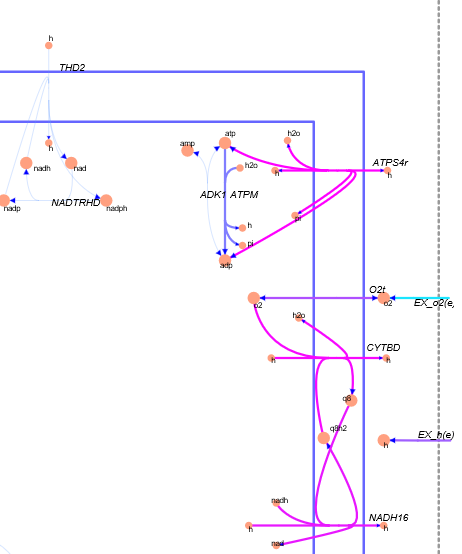

**                    Figure 10: **Close-up of the oxidative phosphorylation section of the *E.coli *core map in aerobic conditions with glucose as the sole carbon source (see Figure 7).

***ATP Production***

Now let's explore in more detail the **production and consumption of atp[c] in the core model**. The** atp[c] produced by ATPS4r is added to the total cellular atp[c] flux that provides the cell's energy.** Remember that** in aerobic conditions, atp[c] is produced by both substrate phosphorylation and oxidative phosphorylation**. All of the reactions that either produce or consume atp[c] can be found using the "surfNet" COBRA toolbox function.  *[Timing: Seconds]*

surfNet(model, 'atp[c]', 0,FBAsolution.x,1,1)


Met #17  atp[c], ATP, C10H12N5O13P3

Consuming reactions with non-zero fluxes :
  #11  ATPM (8.39), Bd: 8.39 / 1000, ATP maintenance requirement, grRules: 
atp[c] + h2o[c]   ->   adp[c] + h[c] + pi[c] 
  #13  Biomass_Ecoli_core_w_GAM (0.873922), Bd: 0 / 1000, Biomass Objective Function with GAM, grRules: 
1.496 3pg[c] + 3.7478 

These results show that under aerobic conditions with glucose as the sole carbon source there are four producers of atp[c] within the core model. These include ATPS4r (oxidative phosphorylation) as the primary contributor and PGK, PYK, and SOCAS (substrate phosphoylation) as secondary sources. This also shows the consumers to be GLNS, PFK, ATPM and the biomass function. As we will see later, the atp[c] associated with PFK is required by the glycolysis pathway. The atp[c] used by ATPM must be greater than or equal to 8.39 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ to allow the cell to grow. Finally **the biomass function shows that 52.27 **$\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$**(0.873922 x 59.81) is used for the cell's biosynthesis needs.** 

One of the important concepts associated with these constraint-based steady state models is that the** total cell fluxes for key cofactors like atp[c] and adp[c] must be equal**. This means that for every atp[c] metabolite that is produced, one adp[c] metabolite will be consumed, but to maintain the mass balance throughout the cell somewhere else in the cell an adp[c] molecule will be created from another atp[c] molecule. Thus, the **total cellular atp[c] flux must equal the total cellular adp[c] flux.** This can be observed using the COBRA Toolbox function called "**computeFluxSplits**" as shown below. *[Timing: Seconds]*

[P, C, vP, vC] = computeFluxSplits(model, {'adp[c]'}, FBAsolution.x);
total_adp_flux = sum(vP)

total_adp_flux = 68.3601

[P, C, vP, vC] = computeFluxSplits(model, {'adp[c]'}, FBAsolution.x);
total_adp_flux = sum(vP)

total_adp_flux = 68.3601

These results show that the amount of atp[c] flux in the cell equals the amount of adp[c] flux. Thus, the adp[c]/atp[c] flux ratio is 1. This is also true for nadp[c]/nadph[c] and the nad[c]/nadh[c] flux ratios. 

Another way to explore the ATPS4r's ability to produce atp[c] is through the use of robustness analysis [12]. Assuming that the objective function is the biomass function (growth-rate), then the following simulation illustrates that the maximum atp[c] flux that can be supported by ATPS4r under aerobic conditions with glucose as the sole carbon source. *[Timing: Minutes]*

model = changeRxnBounds(model,'EX_glc(e)',-10,'l'); % Set maximum glusose uptake
model = changeRxnBounds(model,'EX_o2(e)',-30,'l'); % Set oxygen uptake
[controlFlux, objFlux] = robustnessAnalysis(model,'ATPS4r',100);

Robustness analysis in progress ...
100%    [........................................]


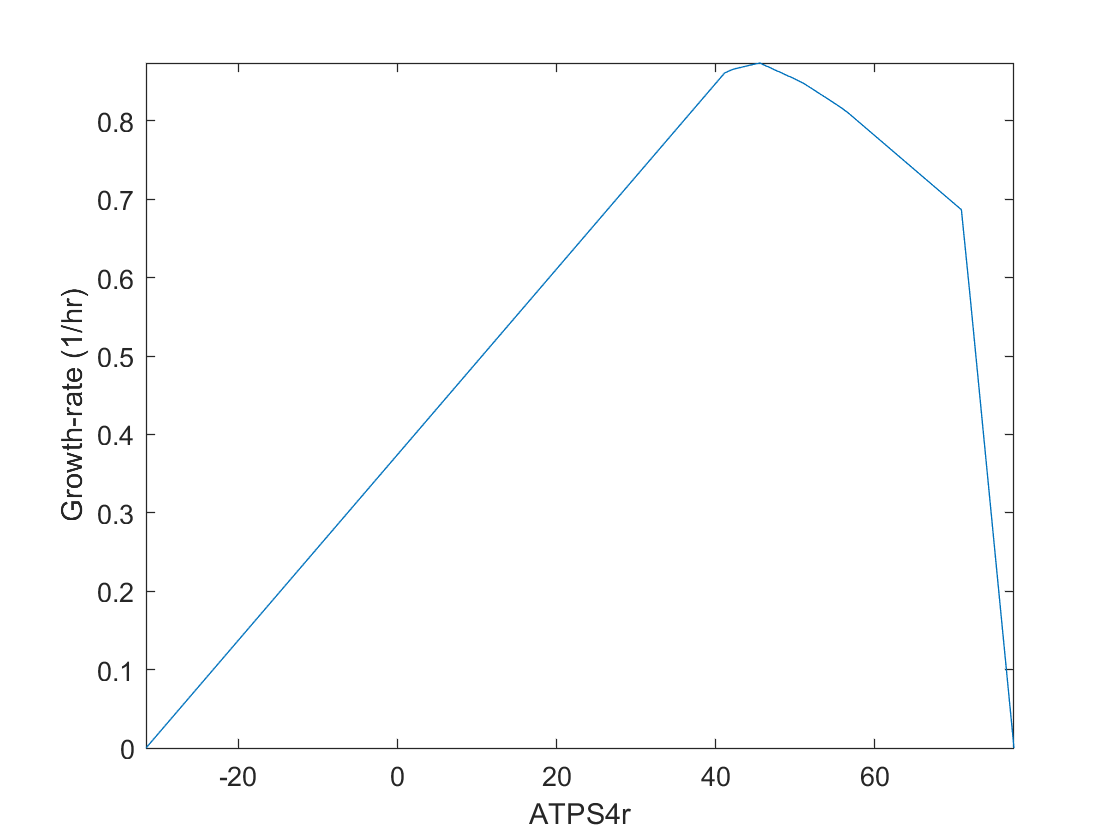

ylabel('Growth-rate (1/hr)');

This graph shows the entire capability of ATPS4r when the carbon source glucose has a maximum uptake rate greater than or equal to  -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. If we start at the left of this of this figure, it can be seen that **ATPS4r takes on negative values** which implies that instead of producing atp[c] through the proton-motive force, it has become an **energy-dependent proton pump removing protons from the cytoplasm and transporting them to the extracellular space**. Note that the growth-rate under these anaerobic conditions is small. As the **flux through ATPS4r becomes positive** it starts producing atp[c] **providing the majority of the atp[c] required for aerobic operation**. At the beginning of aerobic operation there is a nice linear relationship between the produced atp[c] and the growth-rate. Eventually the growth-rate reaches a maximum of 0.8738 ${\textrm{hr}}^{-1}$ when the ATPS4r flux level reaches 45.54 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. **After the maximum growth-rate has been achieved the cell then needs to find ways to recycle the extra ATP**. This can be seen below by fixing the flux through ATPS4r to a value greater than 45.54 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. *[Timing: Seconds]*

model = e_coli_core; % Starting the original model
model = changeRxnBounds(model,'EX_glc(e)',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'ATPS4r',60,'b'); % Fix ATPS4r flux rate
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA
surfNet(model, 'atp[c]', 0,FBAsolution.x,1,1)


Met #17  atp[c], ATP, C10H12N5O13P3

Consuming reactions with non-zero fluxes :
  #7  ADK1 (4.016726), Bd: -1000 / 1000, adenylate kinase, grRules: b0474
amp[c] + atp[c]   ->   2 adp[c] 
  #11  ATPM (13.74626), Bd: 8.39 / 1000, ATP maintenance requirement, grRules: 
atp[c] + h2o[c]   ->   adp[c] + 

map=readCbMap('ecoli_core_map');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawFlux(map, model, FBAsolution.x, options); % Draw the flux values on the map "target.svg"

Document Written


If we compare these results with the previous fluxes calculated for the optimized cell performance under aerobic conditions with a similar glucose carbon source uptake, we can see the differences in atp[c] flux distribution.To start with it can be seen that the flux through ATPM increases (13.74 > 8.39). Notice that ADK1 has been activated to recycle atp[c] to adp[c]. Since the growth-rate decreases, we would also expect the flux used by the biomass function to decrease along with other parts of the cell by selecting alternate pathways to help absorb the extra atp[c]. This is illustrated in the core metabolic map shown below.

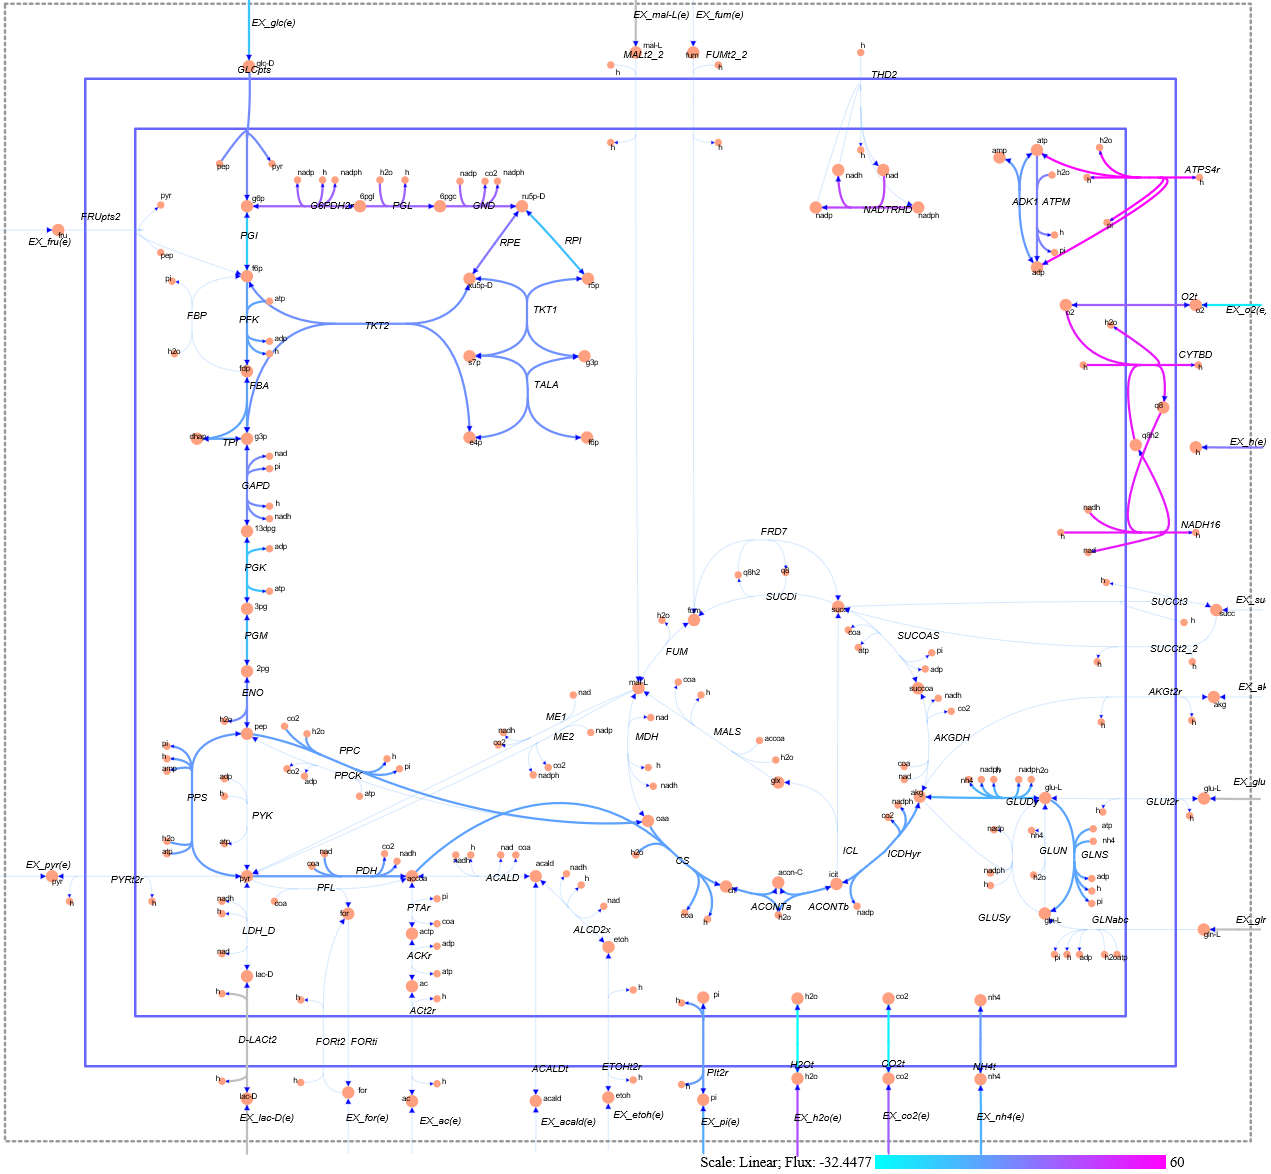

**                                                                                Figure 11. **A screenshot of the core map with ATPS4r fixed at 60$\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. 

***NADH Production***

Now that we have explored the production and consumption of atp[c], let's look at the **producers and consumers of nadh[c]**. *[Timing: Seconds]*

model = e_coli_core; % Starting with the original model
model = changeRxnBounds(model,'EX_glc(e)',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2(e)',-30,'l'); % Set oxygen uptake
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA
surfNet(model,'nadh[c]',0,FBAsolution.x,1,1)


Met #51  nadh[c], Nicotinamide-adenine-dinucleotide-reduced, C21H27N7O14P2

Consuming reactions with non-zero fluxes :
  #67  NADH16 (38.53461), Bd: 0 / 1000, NADH dehydrogenase (ubiquinone-8 & 3 protons), grRules: (b2276 and b2277 and b2278 and b2279 and b2280 and b2281 and b2282 and b2283 and 

Note that in this case, the only consumer of nadh[c] is NAD16 which is the beginning of the electron transport chain. The producing reactions, as we will discuss later, are primarily located in the glycolysis and TCA pathways. Note that for this core model, the **biomass function is also listed as a producer**. Since the biomass function represents all the functionality not included in the core model (e.g. biosynthesis pathways), this implies that **NADH would be produced in other parts of the cell that are not included in this simple core model**. The flux supplied through the biomass function is calculated by multiplying the total biomass flux (0.873922) times the nadh[c] biomass function coefficient (3.547) to yielding a total nadh[c] biomass flux of 3.0998 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. This can also be calculated using the COBRA Toolbox function "computeFluxSplits" as follows. *[Timing: Seconds]*

[nadh_P, nadh_C, nadh_vP, nadh_vC] = computeFluxSplits(model, {'nadh[c]'}, FBAsolution.x);
[~,nadh_rxnID] = ismember('Biomass_Ecoli_core_w_GAM',model.rxns);
nadhBiomassFlux = nadh_vP(nadh_rxnID)

nadhBiomassFlux = 3.0998

***NADPH production***

Finally, we can also obtain this same information for nadph[c], the **reducing power for cellular biosynthesis.** *[Timing: Seconds]*

surfNet(model,'nadph[c]',0,FBAsolution.x,1,1)


Met #53  nadph[c], Nicotinamide-adenine-dinucleotide-phosphate-reduced, C21H26N7O17P3

Consuming reactions with non-zero fluxes :
  #13  Biomass_Ecoli_core_w_GAM (0.873922), Bd: 0 / 1000, Biomass Objective Function with GAM, grRules: 
1.496 3pg[c] + 3.7478 accoa[c] + 59.81 atp[c] + 0.361 e4p[c] + 0.0709 f6p[c] + 0.129 g3p[c] 
  + 0.205 g6p[c] + 0.2557 

Due to the simplicity of the ***E.coli *****core model, most of the nadph[c] is consumed by the biomass function (0.873922 x 13.0279 = 11.385) to support the cell's biosynthesis needs**. The other consumer is the nitrogen metabolism (GLUDy). On the other hand, nadph[c] is produced by reactions in the oxidative phosphorylation pathways, pentose phosphate pathway, and the TCA cycle. It is worth pointing out that in the larger models, that incorporate most of the cells biosynthesis pathways, the number of reactions consuming nadph[c] could be very large. *[Timing: Seconds]*

***Anaerobic Respiration***

Now let's turn our attention to anaerobic cell operation. During aerobic respiration, oxygen is the terminal electron acceptor for the electron transport chain, which yields the bulk of atp[c] required for biosynthesis. **Anaerobic respiration refers to respiration without molecular oxygen**. For **anaerobic respiration, *****E. coli***** only generates atp[c] by substrate level phosphorylation**. Glycolysis results in the net production of two atp[c] per glucose by substrate level phosphorylation, but this is low compared to the total atp[c] production of 17.5 atp[c] per glucose for aerobic respiration [1]. 

The **substrates of fermentation are typically sugars**, so during **fermentative growth,** it is** necessary for each cell to support large flux values through glycolysis to generate sufficient atp[c] to drive cell growth**. Glycolysis also produces two molecules of nadh[c] for each molecule of glucose [1]. As a result, **nadh[c] must be reoxidized by fermentation in order to regenerate nad[c] necessary to maintain the oxidation-reduction balance of the cell.** 

Figure 12 is a map of anaerobic operation using glucose as the only carbon source.

model = e_coli_core; % Starting with the original model
model = changeRxnBounds(model,'EX_glc(e)',-10,'l'); % Set maximum glusose uptake
model = changeRxnBounds(model,'EX_o2(e)',-0,'l'); % Set maximum oxygen uptake
model = changeObjective(model,'Biomass_Ecoli_core_w_GAM'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA
map=readCbMap('ecoli_core_map');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawFlux(map, model, FBAsolution.x, options); % Draw the flux values on the map "target.svg"

Document Written


A screenshot of the produced map of anaerobic operation is shown below.

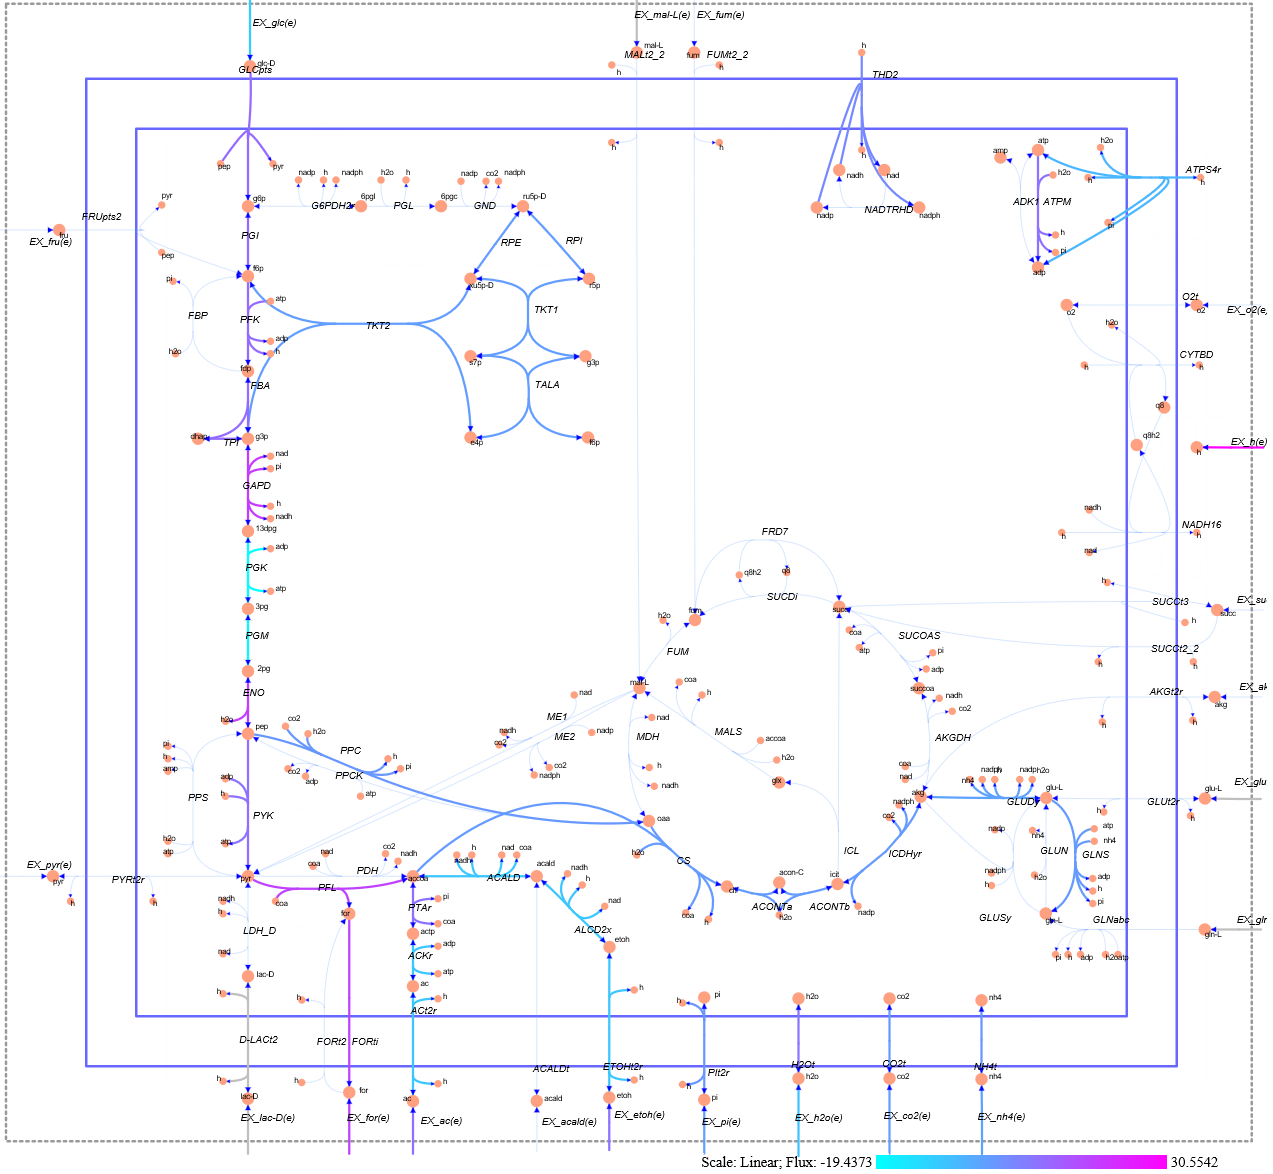

**Figure 12.** Network map of the *E.coli* core model with glucose as the carbon source (EX_glc(e) $\ge$ -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$) in an anaerobic environment (EX_o2(e) $\ge$ 0 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$).

Note that for **anaerobic operation the flux through oxidative phosphorylation pathways (electron transport chain) is zero**. Let's look at the nonzero fluxes associated with anaerobic operation to understand the role of THD2 and ATPS4r. *[Timing: Seconds]*

Reactions = transpose({'ATPS4r','THD2'});
[~,rxnID] = ismember(Reactions,model.rxns);
printLabeledData(Reactions,FBAsolution.x(rxnID))

ATPS4r              	      -5.452
THD2                	       3.629


Now let's look at the fomulas for these reactions to understand what is happening in this condition. *[Timing: Seconds]*

printRxnFormula(model,Reactions)

ATPS4r	adp[c] + 4 h[e] + pi[c] 	<=>	atp[c] + h2o[c] + 3 h[c] 
THD2	2 h[e] + nadh[c] + nadp[c] 	->	2 h[c] + nad[c] + nadph[c] 


ans = 2×1 cell array
    {'adp[c] + 4 h[e] + pi[c]  <=> atp[c] + h2o[c] + 3 h[c] '    }
    {'2 h[e] + nadh[c] + nadp[c]  -> 2 h[c] + nad[c] + nadph[c] '}


Since the flux for** ATPS4r is negative, we can assume that ATPS4r is operating in reverse and pumping protons from the cytoplasm into the extracellular space**. Some of these protons can now be used by **THD2 to convert nadh[c], which is not needed for the electron transport chain, into nadph[c] where they can be used for cellular biosynthesis**.

All the nonzero fluxes for this anaerobic example are printed below. *[Timing: Seconds]*

printFluxVector(model,FBAsolution.x,true) % only print nonzero reaction fluxes 

ACALD               	      -8.279
ACKr                	      -8.504
ACONTa              	      0.2284
ACONTb              	      0.2284
ACt2r               	      -8.504
ALCD2x              	      -8.279
ATPM                	        8.39
ATPS4r              	      -5.452
Biomass_Ecoli_core_w_GAM	      0.2117
CO2t                	      0.3782
CS                  	      0.2284
ENO                 	       19.12
ETOHt2r             	      -8.279
EX_ac(e)            	       8.504
EX_co2(e)           	     -0.3782
EX_etoh(e)          	       8.279
EX_for(e)           	        17.8
EX_glc(e)           	         -10
EX_h(e)             	       30.55
EX_h2o(e)           	      -7.116
EX_nh4(e)           	      -1.154
EX_pi(e)            	     -0.7786
FBA                 	       9.789
FORti               	        17.8
GAPD                	       19.44
GLCpts              	          10
GLNS                	     0.05412
GLUDy               	        -1.1
H2Ot                	       7.116
ICDHyr    

So one question that could be asked is this anaerobic environment is, **where is the nadh[c] produced and where is it consumed.** Using "surfNet" we can find out. *[Timing: Seconds]*

surfNet(model, 'nadh[c]',0,FBAsolution.x,1,1)


Met #51  nadh[c], Nicotinamide-adenine-dinucleotide-reduced, C21H27N7O14P2

Consuming reactions with non-zero fluxes :
  #1  ACALD (-8.279455), Bd: -1000 / 1000, acetaldehyde dehydrogenase (acetylating), grRules: (b0351 or b1241)
acald[c] + coa[c] + nad[c]   <-   accoa[c] + h[c] + nadh[c] 
  #10  

In this case, the **nadh[c] is primarily used to support mixed fermentation through the ethanol pathway.**  This will be described in the fermentation section. 

Now let's explore the production of atp[c] in an anaerobic environment. *[Timing: Seconds]*

surfNet(model, 'atp[c]',0,FBAsolution.x,1,1)


Met #17  atp[c], ATP, C10H12N5O13P3

Consuming reactions with non-zero fluxes :
  #11  ATPM (8.39), Bd: 8.39 / 1000, ATP maintenance requirement, grRules: 
atp[c] + h2o[c]   ->   adp[c] + h[c] + pi[c] 
  #12  ATPS4r (-5.452053), Bd: -1000 / 1000, ATP synthase (four protons for one ATP), grRules: (((b3736 and b3737 and <a href="ma

As can be seen above, the **production of atp[c] is exclusively through substrate phosphorylation (ACKr, PGK, PYK).**

Finally, the nadph[c] producers and consumers are shown below. *[Timing: Seconds]*

surfNet(model, 'nadph[c]',0,FBAsolution.x,1,1)


Met #53  nadph[c], Nicotinamide-adenine-dinucleotide-phosphate-reduced, C21H26N7O17P3

Consuming reactions with non-zero fluxes :
  #13  Biomass_Ecoli_core_w_GAM (0.211663), Bd: 0 / 1000, Biomass Objective Function with GAM, grRules: 
1.496 3pg[c] + 3.7478 accoa[c] + 59.81 atp[c] + 0.361 e4p[c] + 0.0709 f6p[c] + 0.129 g3p[c] 
  + 0.205 g6p[c] + 0.2557 

Note that the primary producer of nadph[c] in this anaerobic environment is THD2, which converts the surplus nadh[c] to nadph[c].

## 4.B. Glycolysis Pathway

Now that we have completed the exploration of the energy management subsystem of the core model, it is time to start looking at the other included subsytems. **Glycolysis is the metabolic pathway in the *****E.coli *****core model that converts glucose and fructose into pyruvate**. The free energy released in this process is used to **form the high-energy compounds of atp[c] and nadh[c].** The location of the glycolysis pathway on the *E.coli *core map is highlighted in the Figure 13.

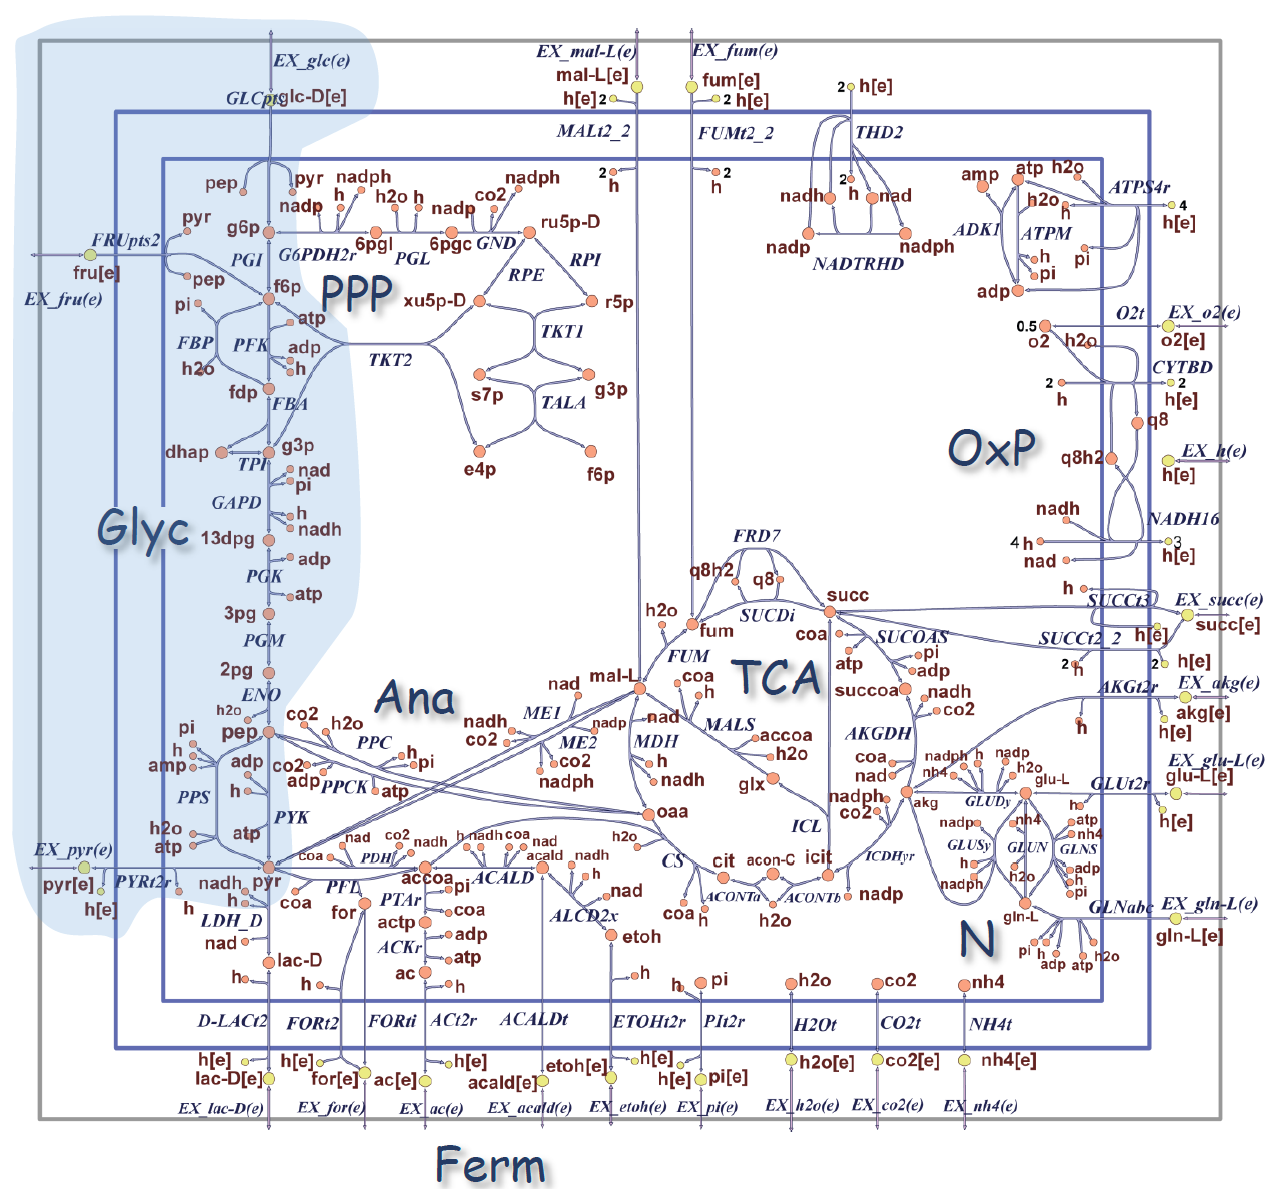

**                                                       Figure 13. **The location of the glycolysis pathway subsystem reactions are highlighted in blue on the *E.coli *core map [3].

A table showing the reactions associated with the glycolysis pathway can be extracted from the core model as follows: *[Timing: Seconds]*

model = changeRxnBounds(model,'EX_glc(e)',-10,'l');
model = changeRxnBounds(model,'EX_o2(e)',-30,'l');
model = changeObjective(model,'Biomass_Ecoli_core_w_GAM');
glycolysisSubystem = {'Glycolysis/Gluconeogenesis'};
glycolysisReactions = model.rxns(ismember(model.subSystems,glycolysisSubystem));
[~,glycolysis_rxnID] = ismember(glycolysisReactions,model.rxns);
Reaction_Names = model.rxnNames(glycolysis_rxnID);
Reaction_Formulas = printRxnFormula(model,glycolysisReactions,0);
T = table(Reaction_Names,Reaction_Formulas,'RowNames',glycolysisReactions)

T = 12×2 table
                           Reaction_Names                                           Reaction_Formulas                         
            ____________________________________________    __________________________________________________________________

    ENO     {'enolase'                                 }    {'2pg[c]  <=> h2o[c] + pep[c] '                                  }
    FBA     {'fructose-bisphosphate aldolase'          }    {'fdp[c]  <=> dhap[c] + g3p[c] '                                 }
    FBP     {'fructose-bisphosphatase'                 }    {'fdp[c] + h2o[c]  -> f6p[c] + pi[c] '                           }
    GAPD    {'glyceraldehyde-3-phosphate dehydrogenase'}    {'g3p[c] + nad[c] + pi[c]  <=> 13dpg[c] + h[c] + nadh[c] '       }
    PDH     {'pyruvate dehydrogenase'                  }    {'coa[c] 

It should be pointed out that although the reaction ***p*****yrvate dehydrogenase (PDH) is included in the glycolysis subsystem it is functionally a better fit in the "Glycoxylate Cycle, Gluconeogenesis, and Anapleurotic Reactions" subsystem**, as described in section 4.E.  

In addition to** providing some atp[c] through substrate phosphorylation** (PGK and PYK), the glycolysis pathway also proves a **major source of nadh[c] (GAPD)** that is used to power the electron transport chain. It also** supplies several key precursors needed for the biosynthesis pathways**. These precursors include: D-Glucose 6-phosphate (g6p[c]) a precursor for sugar nucleotides, D-Fructose 6-phosphate (f6p[c]) a precursor for amino sugars, glyceraldehyde 3-phosphate (g3p[c]) a precursor for phospholipids, 3-Phospho-D-glycerate (3pg[c]) a precursor for cysteine, glycine, and serine, phosphoenolpyruvate (pep[c]) a precursor for tyrosine, tryptophan and phenylalanine, and finally pyruvate (pyr[c]) the precursor for alanine, leucine, and valine [5]. These precursors and their location on the glycolysis pathway are illustrated in Figure 14.

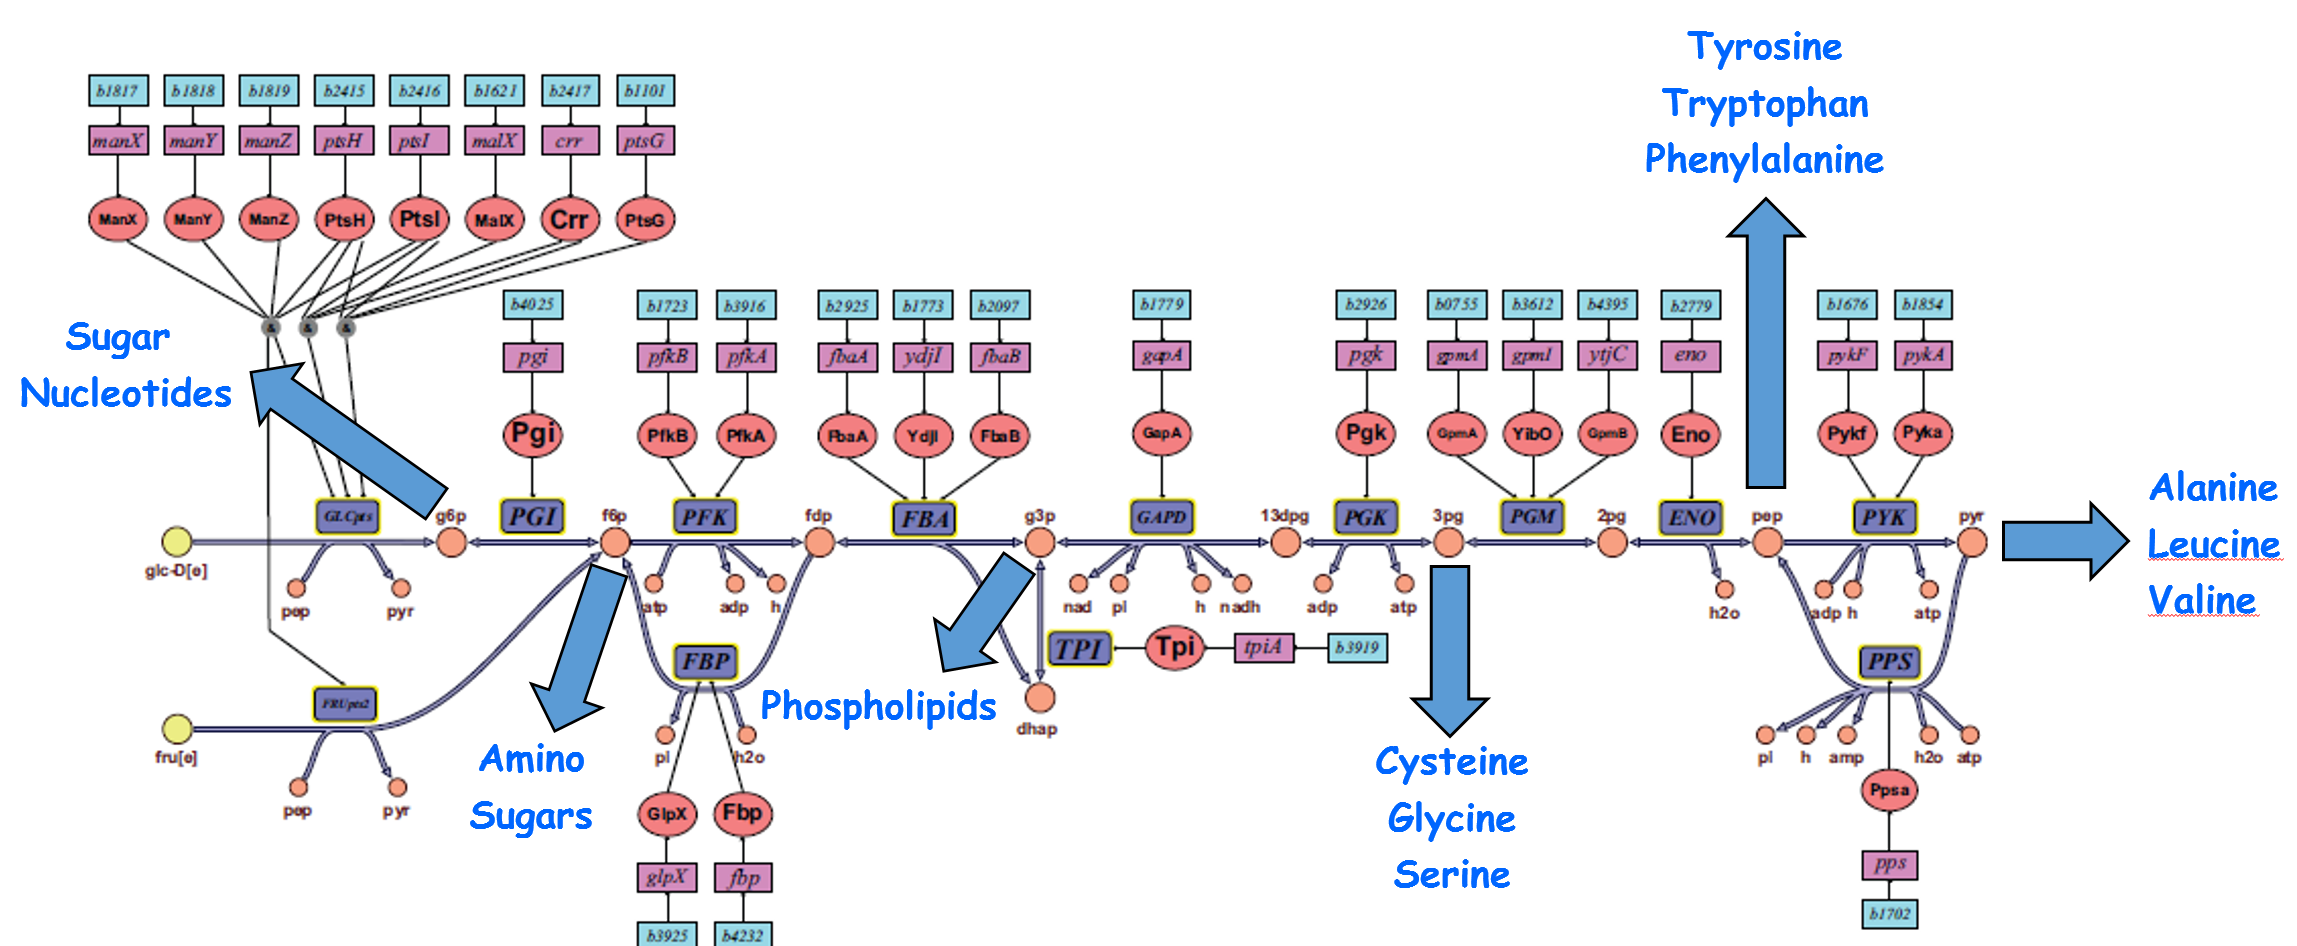

**                                                                                                Figure 14. **Precursors produced in the glycolysis pathway [3]. 

Visualizing the flux though the glycolysis pathways can be seen by using the draw package available with COBRA Toolbox. This is illustrated in the Matlab and COBRA toolbox code listed below for the case of anaerobic operation with** fructose as the carbon source**. *[Timing: Seconds]*

model = e_coli_core; % Starting with the original model
model = changeRxnBounds(model,'EX_glc(e)',0,'l'); 
model = changeRxnBounds(model,'EX_fru(e)',-10,'l'); 
model = changeRxnBounds(model,'EX_o2(e)',-0,'l'); 
model = changeObjective(model,'Biomass_Ecoli_core_w_GAM'); 
FBAsolution = optimizeCbModel(model,'max',0,0);

% Import E.coli core map and adjust parameters
map=readCbMap('ecoli_Textbook_ExportMap');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawFlux(map, model, FBAsolution.x, options);

Document Written


A screenshot of the saved "target.svg" file is shown in the Figure 15.

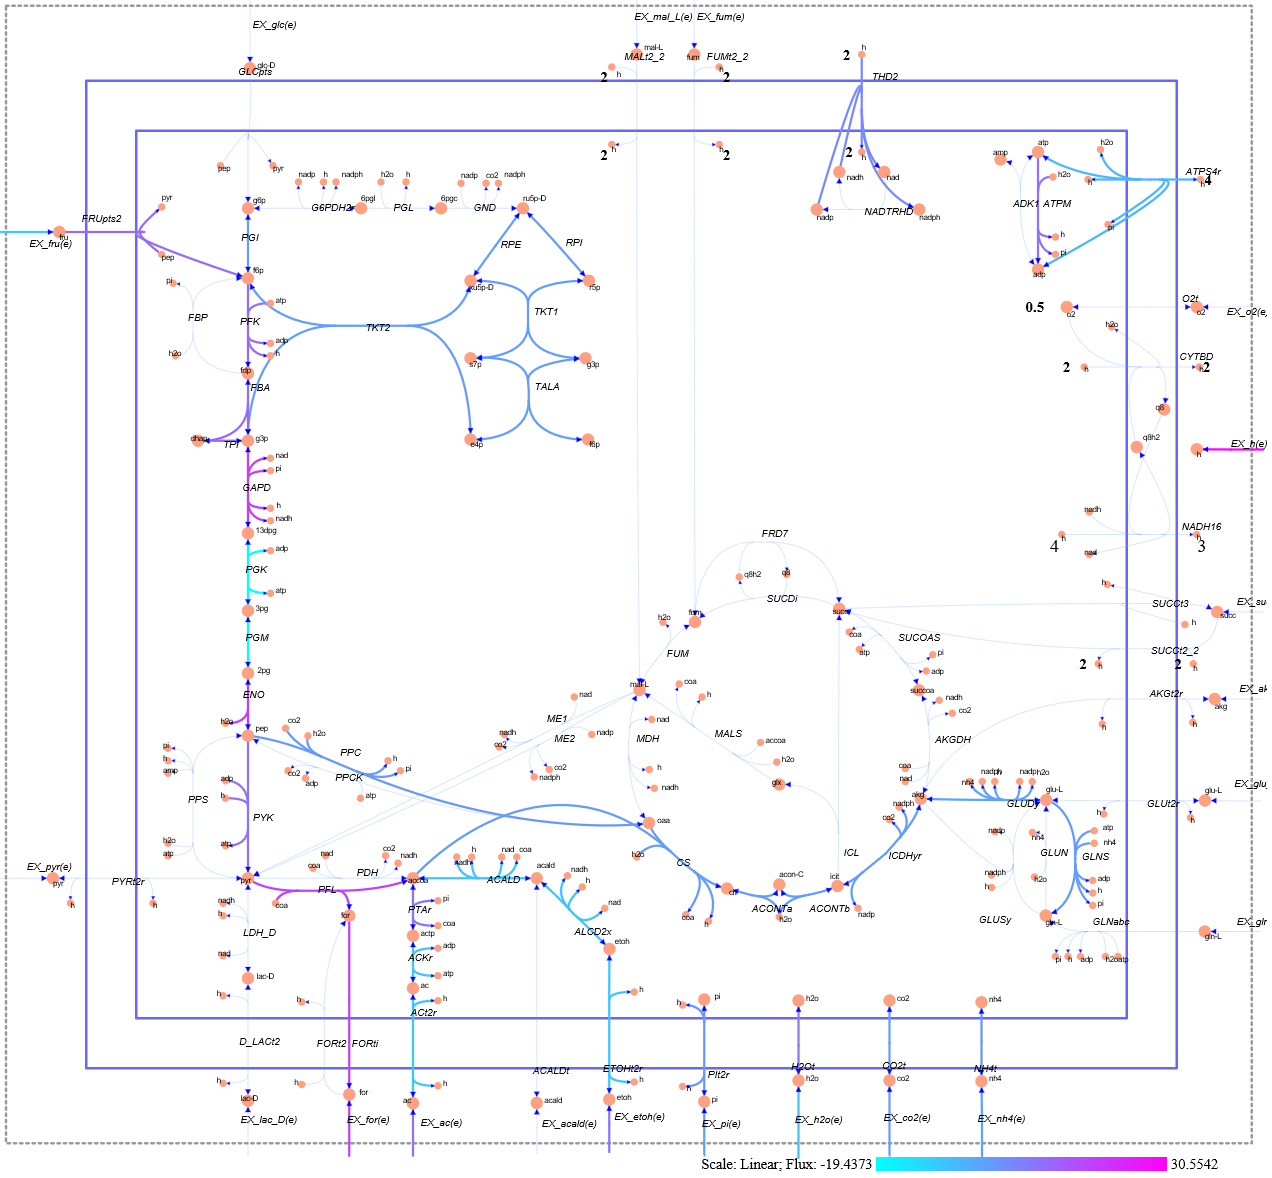

**Figure 15.** Network map of the *E.coli* core model using fructose as the carbon source (EX_fru(e) $\ge$ -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$) in an anaerobic environment (EX_o2(e) $\ge$ 0 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$).

Note that the fructose enters the network on the top left of the map. The detailed flux values for all the active reactions are shown below. *[Timing: Seconds]*

% Print the non-zero flux values
printFluxVector(model, FBAsolution.x, true)    

ACALD               	      -8.279
ACKr                	      -8.504
ACONTa              	      0.2284
ACONTb              	      0.2284
ACt2r               	      -8.504
ALCD2x              	      -8.279
ATPM                	        8.39
ATPS4r              	      -5.452
Biomass_Ecoli_core_w_GAM	      0.2117
CO2t                	      0.3782
CS                  	      0.2284
ENO                 	       19.12
ETOHt2r             	      -8.279
EX_ac(e)            	       8.504
EX_co2(e)           	     -0.3782
EX_etoh(e)          	       8.279
EX_for(e)           	        17.8
EX_fru(e)           	         -10
EX_h(e)             	       30.55
EX_h2o(e)           	      -7.116
EX_nh4(e)           	      -1.154
EX_pi(e)            	     -0.7786
FBA                 	       9.789
FORti               	        17.8
FRUpts2             	          10
GAPD                	       19.44
GLNS                	     0.05412
GLUDy               	        -1.1
H2Ot                	       7.116
ICDHyr    

The consumers of precursors formed in the glycolysis pathways can be found using the "surfNet" COBRA Toolbox function. An example looking for both the producers and consumers of **"f6p[c]," a precursor for amino sugars** is shown below. *[Timing: Seconds]*

surfNet(model, 'f6p[c]',0,FBAsolution.x,1,1)


Met #26  f6p[c], D-Fructose-6-phosphate, C6H11O9P

Consuming reactions with non-zero fluxes :
  #13  Biomass_Ecoli_core_w_GAM (0.211663), Bd: 0 / 1000, Biomass Objective Function with GAM, grRules: 
1.496 3pg[c] + 3.7478 accoa[c] + 59.81 atp[c] + 0.361 e4p[c] + 0.0709 f6p[c] + 0.129 g3p[c] 
  + 0.205 g6p[c] + 0.2557 

Note that the **majority of the f6p[c] flux is directed down the glycolysis pathway (PFK)**, a **modest amount is directed to the pentose phosphate pathway** (PGI, TALA, TKT2), with a **small amount directed to the biomass functio**n (0.211663 x 0.0709 = 0.015) which **represents the biosynthesis load of the precursors**. A similar approach can be used to understand the producer/consumer relationships with the other glycolytic precursors. 

Using the COBRA Toolbox, it is possible to create a table of reactions and their flux values for both glycolysis supported carbon sources, glucose and fructose. This is illustrated below. *[Timing: Seconds]*

% Starting with the original model
model = e_coli_core; 

% Obtain the rxnIDs for the glycolysis pathway reactions
[tmp,glycolysis_rxnID] = ismember(glycolysisReactions,model.rxns); 

% Glucose aerobic flux
FBAsolution = optimizeCbModel(model,'max',0,0);
Glucose_Aerobic_Flux = FBAsolution.x(glycolysis_rxnID);

% Fructose aerobic flux
model = changeRxnBounds(model,'EX_glc(e)',-0,'l');
model = changeRxnBounds(model,'EX_fru(e)',-10,'l');
FBAsolution = optimizeCbModel(model,'max',0,0);
Fructcose_Aerobic_Flux = FBAsolution.x(glycolysis_rxnID);

% Set anaerobic conditions
model = changeRxnBounds(model,'EX_o2(e)',-0,'l');

% Glucose anaerobic flux
model = changeRxnBounds(model,'EX_glc(e)',-10,'l');
FBAsolution = optimizeCbModel(model,'max',0,0);
Glucose_Anaerobic_Flux = FBAsolution.x(glycolysis_rxnID);

% Fructose anaerobic flux
model = changeRxnBounds(model,'EX_glc(e)',-0,'l');
model = changeRxnBounds(model,'EX_fru(e)',-10,'l');
FBAsolution = optimizeCbModel(model,'max',0,0);
Fructose_Anaerobic_Flux = FBAsolution.x(glycolysis_rxnID);

T = table(Glucose_Aerobic_Flux,Fructcose_Aerobic_Flux,Glucose_Anaerobic_Flux,...
    Fructose_Anaerobic_Flux,'RowNames',glycolysisReactions)

T = 12×4 table
            Glucose_Aerobic_Flux    Fructcose_Aerobic_Flux    Glucose_Anaerobic_Flux    Fructose_Anaerobic_Flux
            ____________________    ______________________    ______________________    _______________________

    ENO            14.716                   14.716                    37.855                      19.121       
    FBA            7.4774                   7.4774                    19.486                      9.7895       
    FBP                 0                        0                         0                           0       
    GAPD           16.024                   16.024                    38.628                      19.437       
    PDH            9.2825                   9.2825                         0               

From this table, it can be seen that in all four situations, the flux flows from the carbon source at the top left of the metabolic maps down the glycolysis pathway to form pyruvate in the lower right. In aerobic conditions, part of the flux is diverted to the G6PDH2r entrance to the pentose phosphate pathways. For the anaerobic case, the flux is only diverted to the lower half of the pentose phosphate pathway (TKT2) to produce the pentose phosphate pathway precursors. Also note that the flux through GAPD has almost doubled since the number of g3p[c] metabolites leaving the FBA and TPI reaction are double the number of fdp[c] metabolites entering FBA. This is possible since the output of FBA provides both a molecule of g3p[c] and a molecule of dhap[c]. The dhap[c] is rapidly converted to g3p[c] thus creating the effect of doubling the g3p[c] entering GAPD. A more detailed understanding of the fluxes through glycolysis using the COBRA toolbox is left as an exploration opportunity for the reader.